singleChLoc = "C:\Users\DELL\Documents\SP Cup\ROBOVOX_SP_CUP_2024\data\single-channel";
enrollloc = fullfile(singleChLoc, "enrollment");
spk_labels_enroll = filenames2labels(enrollloc, ExtractBefore = "-", FileExtensions = ".wav")

spk_labels_enroll = 225×1 categorical array
     spk_10 
     spk_10 
     spk_10 
     spk_11 
     spk_11 
     spk_11 
     spk_12 
     spk_12 
     spk_12 
     spk_13 
     spk_13 
     spk_13 
     spk_14 
     spk_14 
     spk_14 
     spk_15 
     spk_15 
     spk_15 
     spk_16 
     spk_16 
     spk_16 
     spk_17 
     spk_17 
     spk_17 
     spk_18 
     spk_18 
     spk_18 
     spk_19 
     spk_19 
     spk_19 



ads = audioDatastore(enrollloc);
ads.Labels = spk_labels_enroll;
ads

ads =   audioDatastore with properties:

                       Files: {
                              ' ...\data\single-channel\enrollment\spk_10-10_21_0_0_d2_ch5.wav';
                              ' ...\data\single-channel\enrollment\spk_10-10_21_0_0_d3_ch5.wav';
                              ' ...\data\single-channel\enrollment\spk_10-10_21_0_0_d4_ch5.wav'
                               ... and 222 more
                              }
                     Folders: {
                              ' ...\Documents\SP Cup\ROBOVOX_SP_CUP_2024\data\single-channel\enrollment'
                              }
                      Labels: [spk_10; spk_10; spk_10 ... and 222 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


[adsTrain,adsTest] = splitEachLabel(ads,0.8);
adsTrain

adsTrain =   audioDatastore with properties:

                       Files: {
                              ' ...\data\single-channel\enrollment\spk_10-10_21_0_0_d2_ch5.wav';
                              ' ...\data\single-channel\enrollment\spk_10-10_21_0_0_d3_ch5.wav';
                              ' ...\data\single-channel\enrollment\spk_11-11_22_1_0_d1_ch5.wav'
                               ... and 147 more
                              }
                     Folders: {
                              ' ...\Documents\SP Cup\ROBOVOX_SP_CUP_2024\data\single-channel\enrollment'
                              }
                      Labels: [spk_10; spk_10; spk_11 ... and 147 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


fs = 16000;
windowLength = round(0.03*fs);
overlapLength = round(0.025*fs);
afe = audioFeatureExtractor(SampleRate=fs, ...
    Window=hamming(windowLength,"periodic"),OverlapLength=overlapLength, ...
    zerocrossrate=true,shortTimeEnergy=true,pitch=true,mfcc=true);

featureMap = info(afe)

featureMap = struct with fields:
               mfcc: [1 2 3 4 5 6 7 8 9 10 11 12 13]
              pitch: 14
      zerocrossrate: 15
    shortTimeEnergy: 16


features = [];
labels = [];
energyThreshold = 0.005;
zcrThreshold = 0.2;

allFeatures = extract(afe,adsTrain);
allLabels = adsTrain.Labels;

for ii = 1:numel(allFeatures)

    thisFeature = allFeatures{ii};

    isSpeech = thisFeature(:,featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = thisFeature(:,featureMap.zerocrossrate) < zcrThreshold;

    voicedSpeech = isSpeech & isVoiced;

    thisFeature(~voicedSpeech,:) = [];
    thisFeature(:,[featureMap.zerocrossrate,featureMap.shortTimeEnergy]) = [];
    label = repelem(allLabels(ii),size(thisFeature,1));
    
    features = [features;thisFeature];
    labels = [labels,label];
end

M = mean(features,1);
S = std(features,[],1);
features = (features-M)./S;

trainedClassifier = fitcknn(features,labels, ...
    Distance="cosine", ...
    NumNeighbors=5, ...
    DistanceWeight="squaredinverse", ...
    Standardize=false, ...
    ClassNames=unique(labels));

k = 5;
group = labels;
c = cvpartition(group,KFold=k); % 5-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,CVPartition=c);

validationAccuracy = 1 - kfoldLoss(partitionedModel,LossFun="ClassifError");
fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);


Validation accuracy = 92.96%


features = [];
labels = [];
numVectorsPerFile = [];

allFeatures = extract(afe,adsTest);
allLabels = adsTest.Labels;

for ii = 1:numel(allFeatures)

    thisFeature = allFeatures{ii};

    isSpeech = thisFeature(:,featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = thisFeature(:,featureMap.zerocrossrate) < zcrThreshold;

    voicedSpeech = isSpeech & isVoiced;

    thisFeature(~voicedSpeech,:) = [];
    numVec = size(thisFeature,1);
    thisFeature(:,[featureMap.zerocrossrate,featureMap.shortTimeEnergy]) = [];
    
    label = repelem(allLabels(ii),numVec);
    
    numVectorsPerFile = [numVectorsPerFile,numVec];
    features = [features;thisFeature];
    labels = [labels,label];
end
features = (features-M)./S;

prediction = predict(trainedClassifier,features);
prediction = categorical(string(prediction));

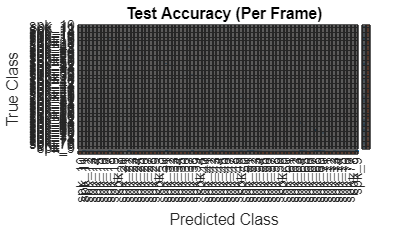

figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(labels(:),prediction,title="Test Accuracy (Per Frame)", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

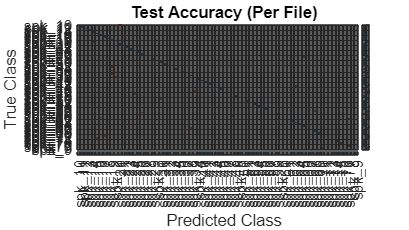

r2 = prediction(1:numel(adsTest.Files));
idx = 1;
for ii = 1:numel(adsTest.Files)
    r2(ii) = mode(prediction(idx:idx+numVectorsPerFile(ii)-1));
    idx = idx + numVectorsPerFile(ii);
end

figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(adsTest.Labels,r2,title="Test Accuracy (Per File)", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");